# Laboratório de Controle - Aula 1 - 2021/1

## Introdução às simulações no Matlab e Simulink

## **Nome**: Arthur Lorencini Bergamaschi

**Atividade 1:** **Simulação de uma função de transferência de primeira ordem**

Na figura 1 é mostrada a resposta ao degrau de um sistema de primeira ordem, destacando a constante de tempo e o tempo de estabelecimento.

Se tiver dúvidas, veja [Constante de tempo](https://pt.wikipedia.org/wiki/Constante_de_tempo)

Atribua a I o valor que recebeu, e execute a próxima seção de código, observando o resultado da simulação à direita.

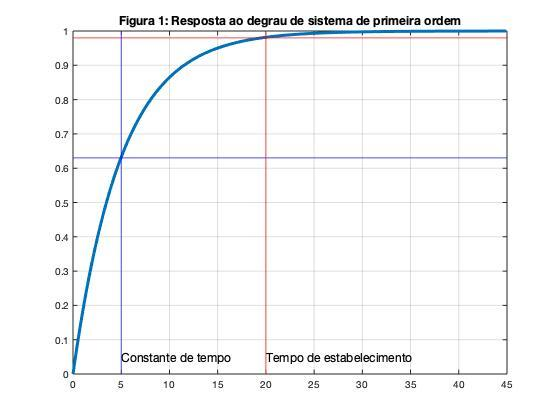

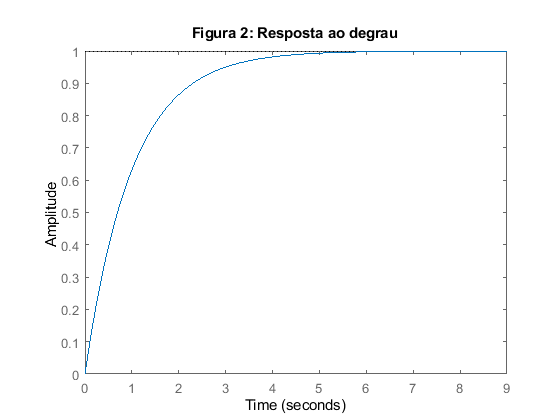

I=1; 
wn=I;
g=tf(1,[I 1]);
figure(2);step(g);title('Figura 2: Resposta ao degrau');

1.1 Observe a Figura 1 e explique como obter a constante de tempo de um sistema de primeira ordem.

Resposta: A constante de tempo de um sistema de primeira ordem pode ser obtida

vendo qual é o tempo em que a amplitude chega a 63% do regime permanente.

1.2 Observe a Figura 2 e obtenha sua constante de tempo (aproximada)

Resposta: A constante de tempo é cerca de 1s.

1.3 Observe a Figura 1 e explique como obter o tempo de estabelecimento de um sistema de primeira ordem. Tendo dúvidas, veja [Tempo de estabelecimento](https://en.wikipedia.org/wiki/Settling_time)

Resposta:O tempo de estabelcimento de um sistema de primeira ordem é obtido

ao ver qual é o tempo em que a amplitude está perto de 5% da amplitude final.

1.4 Observe a Figura 2 e obtenha o tempo de estabelecimento  (aproximado)

Resposta: O tempo de estabelecimento é de cerca de 3s.

**Atividade 2:** **Efeito do ganho na resposta em malha fechada**

Seja a FT $G(s)=\frac{k}{\tau s+1}$. Em malha fechada tem-se $M(s)=\frac{k}{\tau s + 1 + k}$

O slider abaixo muda o ganho k, alterando o único polo de $M(s)$. Para cada alteração, uma nova simulação é feita com o valor escolhido. Experimente.

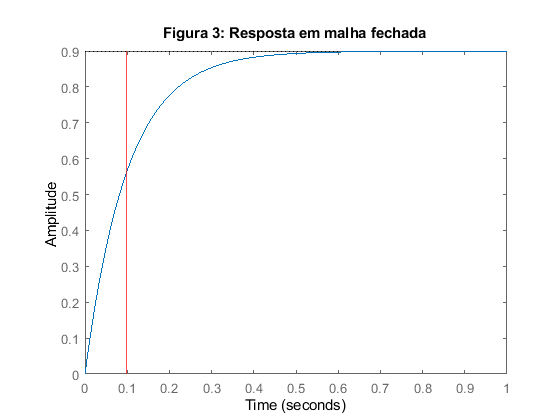


k=8.94;
m=feedback(k*g,1);
figure(3);step(m);title('Figura 3: Resposta em malha fechada');
[y,t]=step(m);
d=sum(y<0.63*y(end));
xline(t(floor(d)),'Color','r');

2.1 Clique 2 vezes sobre o slider e escolha os valores mínimos e máximos, de forma que para o valor mínimo de k se tenha a constante de tempo igual a de malha aberta e para o máximo de k se tenha 10% do valor da constante de tempo em malha aberta.  Quais os valores máximo e mínimo que obteve de k?

Resposta:O valor mínimo de K foi de 0.1 e o máximo foi 8.94.

2.2 Sabendo que o valor de regime de $M(s)$ pode ser obtido pelo teorema do valor final, $Y(s)=M(s)R(s)$, $lim_{s\to 0}s Y(s)= lim_{s\to 0}sM(s)\frac{1}{s}=M(0)$, e usando a figura 3, explique o efeito do ganho k no valor final da saída. Dúvidas, veja [Teorema do valor final](https://pt.wikipedia.org/wiki/Teorema_do_valor_final) . Dica: vejam o comando [freqresp](https://www.mathworks.com/help/control/ref/lti.freqresp.html) para obter $M(0)$.

Resposta: Quanto menor o K, menor é o valor de regime da amplitude. Quanto maior o K, maior é o valor de regime da amplitude

**Atividade 3:** **Avaliação do efeito do ganho na constante de tempo usando múltiplas simulações **

O comando linspace é usado agora para gerar 10 valores de ganho k entre os valores mínimo e máximo que escolheu na atividade 2.1. O formato do comando é k=linspace(kmin,kmax,10). Abaixo a simulação para cada valor de ganho é repetida 10 vezes e uma figura com o ganho versus a constante de tempo é mostrada.

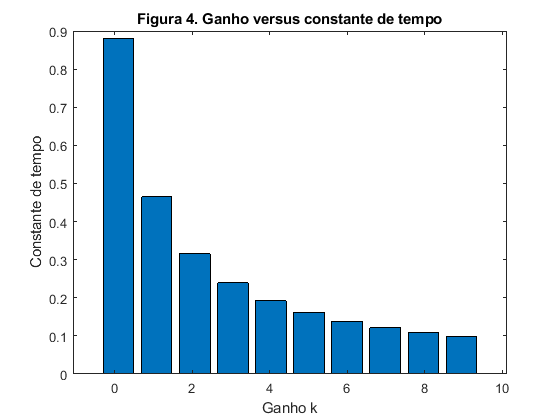

k=linspace(0.1,8.94,10); 
for i=1:10
    m=feedback(k(i)*g,1);
    [y,t]=step(m);
    ct(i)=t(floor(sum(y<0.63*y(end))));
end
figure(4);bar(k,ct);xlabel('Ganho k');ylabel('Constante de tempo');
title('Figura 4. Ganho versus constante de tempo');

 3.1 Explique a Figura 4, levando em consideração a análise que fez na atividade 2.1

Resposta: A Figura 4 mostra que quanto maior o K, menor é a constante de tempo.

**Atividade 4: Simulação do arquivo slx do Simulink**

O comando **sim** é utilizado para simular diagramas do Simulink no ambiente do Matlab. O formato é sim(arquivo,tempo), sendo arquivo uma string e tempo uma constante que define o tempo total de simulação. Exemplo: sim('aula1_R2018.slx',10); Help do [comando sim](https://www.mathworks.com/help/simulink/slref/sim.html).

A figura 5 mostra o diagrama simulado. É aplicado um degrau R, e obtem-se a saída Y. Tanto o sinal de entrada quanto de saída são mostrados no bloco scope de saída, e são gravados em uma variável X, que é plotada no ambiente do Matlab, e é uma matriz da forma X=[ tempo Entrada Saída]. A sintaxe dos comandos para simular e obter X depende da versão do Matlab, conforme abaixo:

**Matlab 2018 em diante**

out=sim(arquivo,Tempo);

Y=out.X(:,[2,3]);

t=out.tout;

**Matlab anterior a 2018**

sim(arquivo,Tempo);

Y=X(:,[2,3]);

t=X(:,1);

O parâmetro que afeta a simulação é wn, que é definido no ambiente do Matlab antes de cada simulação.

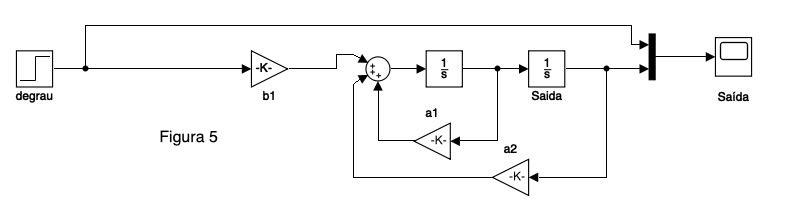

**Atividade 4.1: **Simular o diagrama usando os comandos adequados e com o tempo adequado, e plotar a resposta e a entrada aplicada.

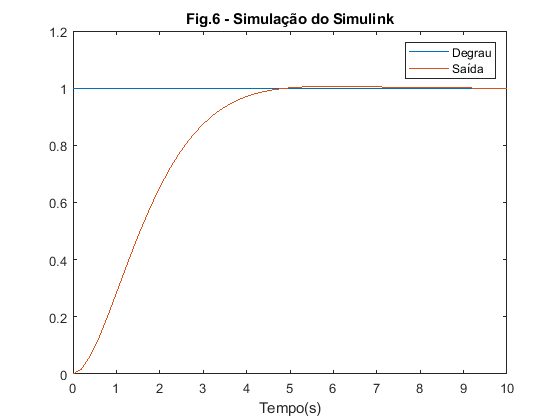

Tempo=10;
out=sim("aula1_R2018.slx",Tempo);
Y=out.X(:,[2,3]);
t=out.tout;
plot(t,Y);legend('Degrau','Saída');xlabel('Tempo(s)');title('Fig.6 - Simulação do Simulink');

datetime('now')

ans = datetime
   16-Jun-2021 10:50:31


pwd

ans = 'C:\Users\malaquias\Desktop\Aula1'